# **graycomatrix**

25/04/22

**Integrantes:**

Kristen Aideé Pérez Alvarez --> A00829551

René Jahaziel Rangel Yáñez --> A00826919

Maxine Annel Pacheco Ramírez --> A01551933

Create Gray-Level Co-occurrence Matrix for Grayscale Image 

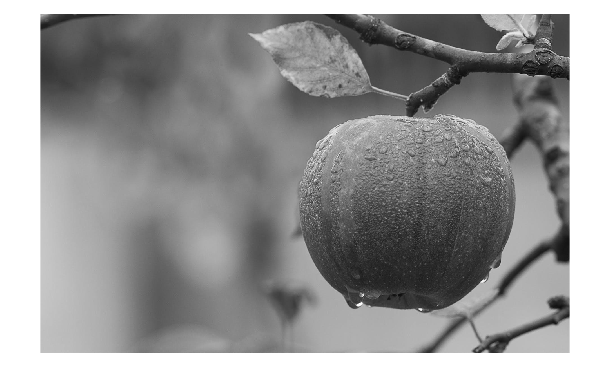

I = imread('gray.jpeg'); % lee la imagen en escala de grises
imshow(I) % muestra la imagen


glcm = graycomatrix(I,'Offset',[2 0]) % calcula la matriz de co-ocurrencia de niveles de grises. Esto se hace por la proximidad horizontal de los pixeles.

glcm =        12580        4226         241          62          46          16           0           0
        4298      185276       26350        1703         273         134          26           2
         219       26705      365141       28780        3881         808         156          16
          48        1283       29313      475855       31386        3395         675          53
           2         149        2904       31458      497289       20066        1508          96
           2          33         382        2737       20521      430988        5759         193
           0           7          85         377        1262        6379       32681         527
           0           1          12          33          96         172         573         521


Create Gray-Level Co-occurrence Matrix (GLCM) Returning Scaled Image

I = [ 1 1 5 6 8 8; 2 3 5 7 0 2; 0 2 3 5 6 7] % se crea una matriz 3x6

I =      1     1     5     6     8     8
     2     3     5     7     0     2
     0     2     3     5     6     7



[glcm,SI] = graycomatrix(I,'NumLevels',9,'GrayLimits',[]) % calcula la matriz de co-ocurrencia de niveles de grises y de una imagen escalada. 

glcm =      0     0     2     0     0     0     0     0     0
     0     1     0     0     0     1     0     0     0
     0     0     0     2     0     0     0     0     0
     0     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     2     1     0
     0     0     0     0     0     0     0     1     1
     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1


SI =      2     2     6     7     9     9
     3     4     6     8     1     3
     1     3     4     6     7     8


Calculate GLCMs using Four Different Offsets

Ii = imread('gray2.jpg'); % lee la imagen en escala de grises
I = rgb2gray(Ii)

I = 1440×2560 uint8 matrix
    88    89    90    91    90    89    88    87    89    89    86    79    71    67    70    73    74    76    79    82    85    87    88    89    90    88    88    91    95    95    92    87    91    89    88    89    90    89    85    82    86    90    89    86    85    88    88    84    84    83
    89    88    88    88    88    88    88    88    85    86    84    79    73    71    75    79    78    79    80    82    84    86    88    89    90    89    88    90    93    94    93    90    88    87    86    86    88    90    90    90    88    90    90    87    86    89    89    85    86    84
    88    87    86    85    85    86    87    89    85    85    84    81    77    76    79    83    84    83    83    83    84    86    88    89    90    89    88    89    91    92    93    93    93    91    89    86    84    85    88    91    89    91    91    88    88    89    89    87    87    84
    87    86    85    85    85    85    86    87    89    89    88    

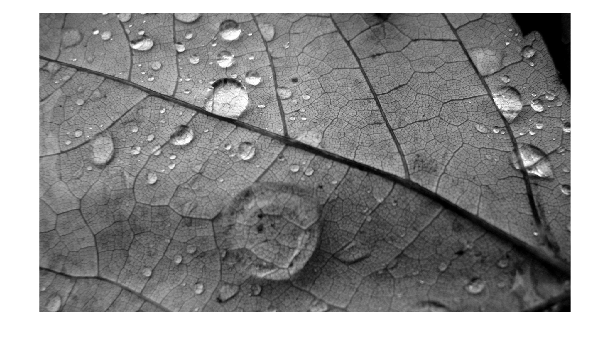

imshow(I) % desplega la imagen

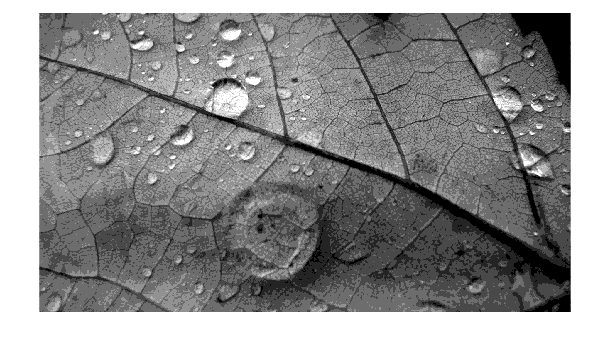


offsets = [0 1; -1 1;-1 0;-1 -1]; % se definen los desplazamientos

[glcms,SI] = graycomatrix(I,'Offset',offsets); % calcula la co-ocurrencia de niveles de grises y da una imagen escalada. Se hace un reescalado de los valores de los datos [0,1].
imshow(rescale(SI)) % muestra la imagen reescalada


whos % devuelve una matriz de cuatro GLCM

  Name            Size                   Bytes  Class     Attributes

  I            1440x2560               3686400  uint8               
  Ii           1440x2560x3            11059200  uint8               
  SI           1440x2560              29491200  double              
  glcm            9x9                      648  double              
  glcms           8x8x4                   2048  double              
  offsets         4x2                       64  double              



Calculate Symmetric GLCM for Grayscale Image

I = imread('gray.jpeg'); % lee la imagen en escala de grises
imshow(I) % despliega la imagen


[glcm,SI] = graycomatrix(I,'Offset',[2 0],'Symmetric',true); % calcula la GLCM utilizando la opción simétrica y devuelve la imagen escalada.
% La GLCM que se crea cuando Symmetric es true es simétrica a la diagonal
glcm

glcm =        25160        8524         460         110          48          18           0           0
        8524      370552       53055        2986         422         167          33           3
         460       53055      730282       58093        6785        1190         241          28
         110        2986       58093      951710       62844        6132        1052          86
          48         422        6785       62844      994578       40587        2770         192
          18         167        1190        6132       40587      861976       12138         365
           0          33         241        1052        2770       12138       65362        1100
           0           3          28          86         192         365        1100        1042


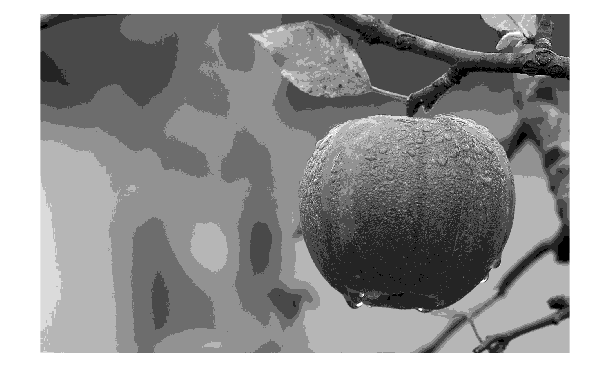


imshow(rescale(SI)) % se desplega la imagen escalada agregando un reescalamiento adicional en el rango [0,1] 



graycomatrix(I,'offset',[0 1],'Symmetric',true) % este GLCM con symmetric true es igual a la suma de las dos GLCM siguientes en donde Symmetric es false

ans =        30016        4236          15           1           0           0           0           0
        4236      401636       29992         284          18           1           2           0
          15       29992      783592       36269        1175          78           4           0
           1         284       36269     1005456       40904        1409          41           2
           0          18        1175       40904     1040650       26029         619          11
           0           1          78        1409       26029      888472        8116          80
           0           2           4          41         619        8116       72720         795
           0           0           0           2          11          80         795        1928



graycomatrix(I,'offset',[0 1],'Symmetric',false) 

ans =        15008        2092           5           1           0           0           0           0
        2144      200818       14954         158          15           1           0           0
          10       15038      391796       17962         663          38           2           0
           0         126       18307      502728       20070         815          25           0
           0           3         512       20834      520325       12628         336           6
           0           0          40         594       13401      444236        3747          41
           0           2           2          16         283        4369       36360         397
           0           0           0           2           5          39         398         964


graycomatrix(I,'offset',[0 -1],'Symmetric',false)

ans =        15008        2144          10           0           0           0           0           0
        2092      200818       15038         126           3           0           2           0
           5       14954      391796       18307         512          40           2           0
           1         158       17962      502728       20834         594          16           2
           0          15         663       20070      520325       13401         283           5
           0           1          38         815       12628      444236        4369          39
           0           0           2          25         336        3747       36360         398
           0           0           0           0           6          41         397         964
